% Principal Component Analysis of whole brain using Aya's EEG dataset
% across time.

% set input and output paths:
input_path = 'H:\My Drive\Data\New Data\EEG epoched\BLA';
output_path = '\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';

% 1- ICA on preprocessed epoched data
% What preprocessing has been done:
% - First prototype the pipeline for BLA (baseline auditory condidtion) for
% the first subject. 
% - Import .set file
file_path = fullfile(input_path,'binepochs filtered ICArej BLAAvgBOS2.set');
EEG = pop_loadset(file_path);

pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS2.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Plotting...


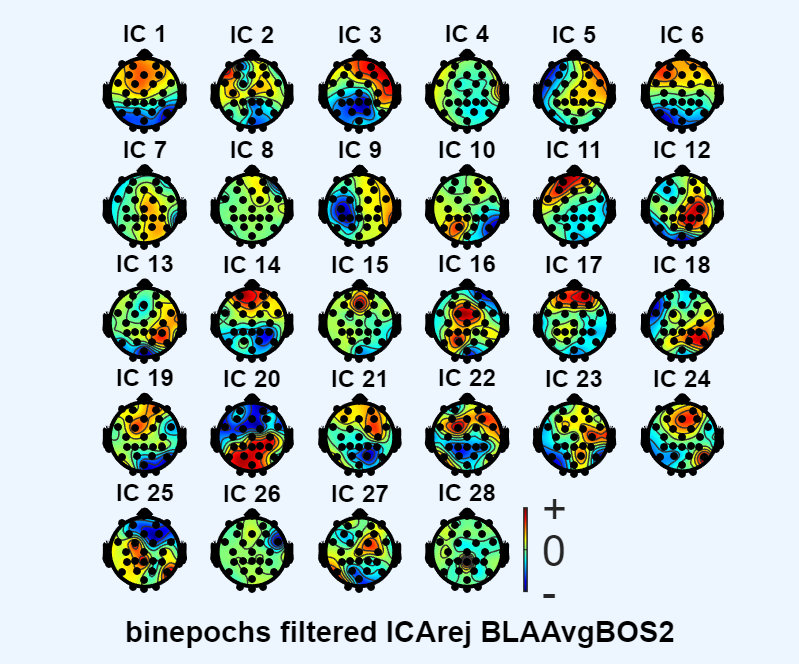

pop_topoplot(EEG, 0, [1:28] ,'binepochs filtered ICArej BLAAvgBOS2',[5 6] ,0,'electrodes','on');

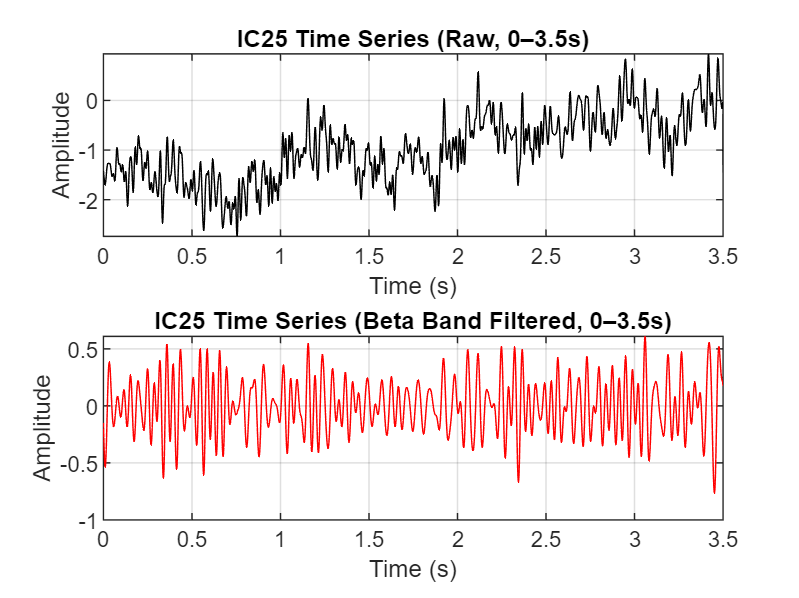


% - First we will do the PCA for just one IC over the somatosensory cortex
% and later loop over all ICs.
% IC25 for BLAAvgBOS2 falls over left central

% - Visualize ICs and chose the IC over left somatosensory cortex
fs = EEG.srate; % Sampling frequency in Hz
ic_data = EEG.icaact(25, :); % IC time series
time_vector = (0:length(ic_data)-1) / fs; % Time in seconds

% - Bandpass filter different EEG bands (theta, alpha, beta, gamma): Here
% we will first focus on beta for its role in attention.
beta_band = [13 30];
% Bandpass filtering:

beta_signal = bandpass(ic_data, beta_band, fs);

% Define time range for plotting (0 to 3.5 seconds)
time_limit = 3.5; % seconds
idx_range = time_vector <= time_limit; % Logical index for the range

% Plot IC time series before and after filtering (limited to 0-3.5s)
figure;
subplot(2,1,1);
plot(time_vector(idx_range), ic_data(idx_range), 'k');
xlabel('Time (s)');
ylabel('Amplitude');
title('IC25 Time Series (Raw, 0–3.5s)');
xlim([0 time_limit]);
grid on;

subplot(2,1,2);
plot(time_vector(idx_range), beta_signal(idx_range), 'r');
xlabel('Time (s)');
ylabel('Amplitude');
title('IC25 Time Series (Beta Band Filtered, 0–3.5s)');
xlim([0 time_limit]);
grid on;


% 2- PCA 

